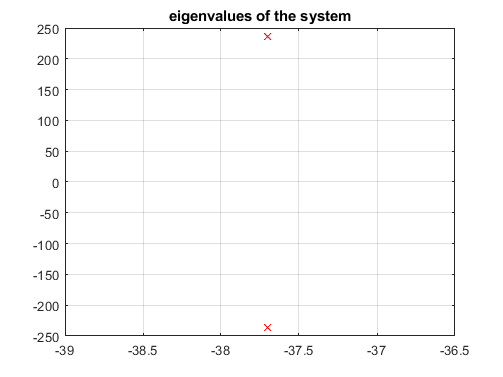

clear; clc;
s= tf('s'); h = 0.001; t = 0:h:0.1;
vs = ones(length(t),1);                    % step excitation
R = 0.1; L = 0.5/377; C = 1/0.2/377;
sys = 1/(R*C*s+L*C*s^2+ 1);                % from vs to capacitor voltage 
eig_sys = pole(sys);
figure;
plot(eig_sys, 'rX');
grid on; title('eigenvalues of the system');

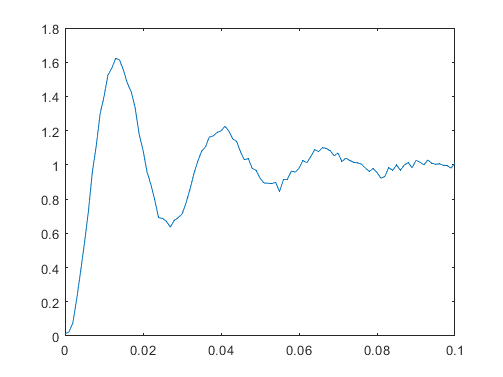

vc = lsim(sys, vs, t); [n_vc, m_vc] = size(vc);
vc1 = vc + (rand(n_vc, m_vc) -0.5)*0.1/max(vc); % add noise
figure;
plot(t, vc1);

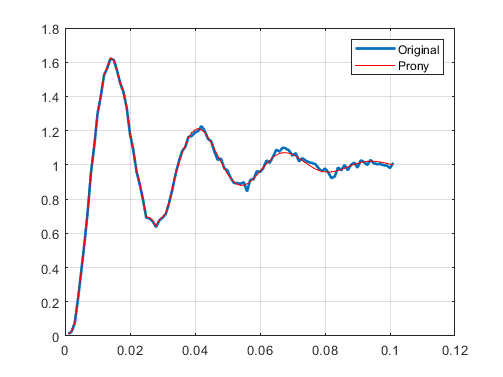

eig_a1 = 1.0e+02 *

  -0.0009 + 0.0000i
  -0.4053 + 2.3602i
  -0.4053 - 2.3602i


m = 3;                                    % order of the system  
y = (vc1); [N, n_ch]=size(y);
eig_a1 = fun_prony(y, h, m)

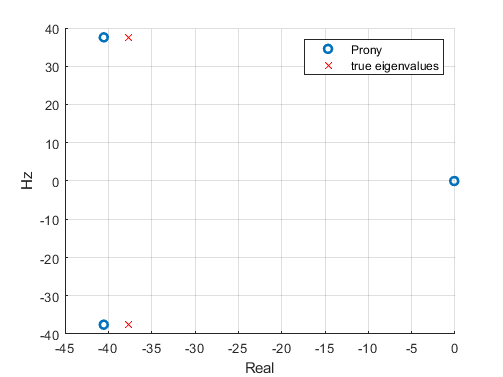

hold on;
plot(real(eig_sys), imag(eig_sys)/2/pi,'rx');
legend('Prony','true eigenvalues');